%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 67);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["iso_code", "continent", "location", "date", "total_cases", "new_cases", "new_cases_smoothed", "total_deaths", "new_deaths", "new_deaths_smoothed", "total_cases_per_million", "new_cases_per_million", "new_cases_smoothed_per_million", "total_deaths_per_million", "new_deaths_per_million", "new_deaths_smoothed_per_million", "reproduction_rate", "icu_patients", "icu_patients_per_million", "hosp_patients", "hosp_patients_per_million", "weekly_icu_admissions", "weekly_icu_admissions_per_million", "weekly_hosp_admissions", "weekly_hosp_admissions_per_million", "total_tests", "new_tests", "total_tests_per_thousand", "new_tests_per_thousand", "new_tests_smoothed", "new_tests_smoothed_per_thousand", "positive_rate", "tests_per_case", "tests_units", "total_vaccinations", "people_vaccinated", "people_fully_vaccinated", "total_boosters", "new_vaccinations", "new_vaccinations_smoothed", "total_vaccinations_per_hundred", "people_vaccinated_per_hundred", "people_fully_vaccinated_per_hundred", "total_boosters_per_hundred", "new_vaccinations_smoothed_per_million", "new_people_vaccinated_smoothed", "new_people_vaccinated_smoothed_per_hundred", "stringency_index", "population_density", "median_age", "aged_65_older", "aged_70_older", "gdp_per_capita", "extreme_poverty", "cardiovasc_death_rate", "diabetes_prevalence", "female_smokers", "male_smokers", "handwashing_facilities", "hospital_beds_per_thousand", "life_expectancy", "human_development_index", "population", "excess_mortality_cumulative_absolute", "excess_mortality_cumulative", "excess_mortality", "excess_mortality_cumulative_per_million"];
opts.VariableTypes = ["categorical", "categorical", "categorical", "datetime", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "double", "double", "double", "double", "double", "double", "string", "double", "double", "string", "string", "double", "double", "double", "double", "double", "string", "string", "string", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["icu_patients", "icu_patients_per_million", "hosp_patients", "hosp_patients_per_million", "weekly_icu_admissions", "weekly_icu_admissions_per_million", "weekly_hosp_admissions", "weekly_hosp_admissions_per_million", "total_tests", "new_tests", "total_tests_per_thousand", "new_tests_per_thousand", "new_tests_smoothed", "new_tests_smoothed_per_thousand", "positive_rate", "tests_per_case", "tests_units", "total_vaccinations", "people_vaccinated", "people_fully_vaccinated", "total_boosters", "new_vaccinations", "new_vaccinations_smoothed", "total_vaccinations_per_hundred", "people_vaccinated_per_hundred", "people_fully_vaccinated_per_hundred", "total_boosters_per_hundred", "new_vaccinations_smoothed_per_million", "new_people_vaccinated_smoothed", "new_people_vaccinated_smoothed_per_hundred", "extreme_poverty", "female_smokers", "male_smokers", "excess_mortality_cumulative_absolute", "excess_mortality_cumulative", "excess_mortality", "excess_mortality_cumulative_per_million"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["iso_code", "continent", "location", "icu_patients", "icu_patients_per_million", "hosp_patients", "hosp_patients_per_million", "weekly_icu_admissions", "weekly_icu_admissions_per_million", "weekly_hosp_admissions", "weekly_hosp_admissions_per_million", "total_tests", "new_tests", "total_tests_per_thousand", "new_tests_per_thousand", "new_tests_smoothed", "new_tests_smoothed_per_thousand", "positive_rate", "tests_per_case", "tests_units", "total_vaccinations", "people_vaccinated", "people_fully_vaccinated", "total_boosters", "new_vaccinations", "new_vaccinations_smoothed", "total_vaccinations_per_hundred", "people_vaccinated_per_hundred", "people_fully_vaccinated_per_hundred", "total_boosters_per_hundred", "new_vaccinations_smoothed_per_million", "new_people_vaccinated_smoothed", "new_people_vaccinated_smoothed_per_hundred", "extreme_poverty", "female_smokers", "male_smokers", "excess_mortality_cumulative_absolute", "excess_mortality_cumulative", "excess_mortality", "excess_mortality_cumulative_per_million"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "date", "InputFormat", "yyyy-MM-dd");

% Import the data
owidcoviddata = readtable("../covid analysis/owid-covid-data.csv", opts);


%% Clear temporary variables
clear opts



countries(1)=owidcoviddata.location(1);
c=1;
% d(c)=1;
for i=2:size(owidcoviddata,1)
    if owidcoviddata.location(i) ~= countries(c)
        c=c+1;
        countries(c)=owidcoviddata.location(i);
    %     d(c)=1;
    % else 
    %     d(c)=d(c)+1;
    end
    % deaths(c,d(c))=owidcoviddata.new_deaths_smoothed_per_million(i);
    % dates(c,d(c))=owidcoviddata.date(d(c));
end


for i=1:size(countries,2)
    kk=owidcoviddata(find(owidcoviddata.location==countries(i)),:);
    d(i)=size(kk,1);
    deaths(i,1:size(kk,1))=kk.new_deaths_smoothed;
    dates(i,1:size(kk,1))=kk.date;
end


unwantedlocations = ["Lower middle income","High income","Low income", "Asia","European Union","Europe", "Africa", "Europa", "World", "South America", "Upper middle income", "North America", "Vanuatu", "Vatican", "United States Virgin Islands", "Turkmenistan", "Turks and Caicos Islands", "Tuvalu", "Tokelau", "Sint Maarten (Dutch part)", "Saint Helena", "Saint Pierre and Miquelon", "Puerto Rico", "Pitcairn", "Palau", "Northern Cyprus", "Northern Ireland", "Northern Mariana Islands", "Niue", "North Korea", "Nauru", "Montserrat", "Jersey", "International", "Guernsey", "Guam", "Greenland", "Falkland Islands", "Faeroe Islands", "England", "Cook Islands", "Cayman Islands", "Bhutan", "Anguilla", "Scotland", "Wales", "Wallis and Futuna", "Western Sahara"];
aas=0;  
wanted_countries(1)=owidcoviddata.location(1);
for i=1:size(countries,2)
     control=true;
    for j=1:size(unwantedlocations,2)
        if countries(i)==unwantedlocations(j)
            control=false;
        end
    end
    if control
        aas=aas+1;
        wanted_countries(end+1)=countries(i);
        kk=owidcoviddata(find(owidcoviddata.location==countries(i)),:);
        deathspermillion(aas,1:size(kk,1))=kk.new_deaths_smoothed_per_million
    end
end

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420


deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0070    0.0140    0.0100    0.0100    0.0100    0.0070    0.0100    0.0100    0.0100    0.0100    0.0240    0.0350    0.0380    0.0350    0.0350    0.0380    0.0420
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510    0.2010    0.3020    0.4020    0.4020    0.3520    0.5030    0.5030    0.5030    0.4520    0.5030    0.5030    0.5030    0.3520    0.3520    0.3520    0.3020    0.1510    0.1510

deathspermillion = 51×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 52×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 53×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 54×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 55×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 56×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 57×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 58×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 59×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 60×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 61×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 62×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 63×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 64×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 65×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 66×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 67×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 68×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 69×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 70×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 71×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 72×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 73×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 74×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 75×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 76×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 77×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 78×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 79×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 80×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 81×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 82×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 83×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 84×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 85×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 86×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 87×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 88×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 89×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 90×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 91×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 92×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 93×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 94×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 95×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 96×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 97×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 98×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 99×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       NaN

deathspermillion = 100×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 101×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 102×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 103×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 104×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 105×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 106×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 107×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 108×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 109×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 110×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 111×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 112×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 113×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 114×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 115×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 116×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 117×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 118×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 119×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 120×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 121×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 122×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 123×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 124×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 125×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 126×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 127×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 128×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 129×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 130×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 131×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 132×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 133×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 134×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 135×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 136×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 137×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 138×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 139×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 140×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 141×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 142×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 143×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 144×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 145×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 146×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 147×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 148×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 149×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 150×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 151×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 152×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 153×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 154×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 155×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 156×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 157×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 158×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 159×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 160×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 161×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 162×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 163×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 164×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 165×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 166×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 167×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 168×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 169×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 170×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 171×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 172×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 173×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 174×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 175×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 176×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 177×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 178×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 179×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 180×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 181×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 182×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 183×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 184×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 185×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 186×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 187×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 188×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 189×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 190×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 191×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 192×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 193×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 194×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 195×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 196×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 197×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 198×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 199×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 200×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

deathspermillion = 201×1106
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.1510    0.2010    0.1510
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0130    0.0220    0.0250    0.0290    0.0380    0.0410    0.0410    0.0480    0.0450
       NaN       NaN       NaN       NaN       NaN       NaN       Na

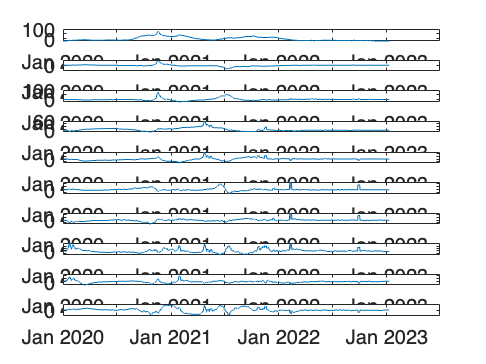


wanted_countries=wanted_countries(2:end);
deaths(isnan(deaths))=0;
deaths=floor(deaths);
%deaths=transpose(deaths);

deathspermillion(isnan(deathspermillion))=0;
%deathspermillion=floor(deathspermillion);
deathspermillion=transpose(deathspermillion);
[m,c]=max(d);
dates_voc=dates(c,:);

[coeff3,score3,latend,tsd,exp3] = pca(deathspermillion,'NumComponents',10);


figure("Name","pca with per million data")
for i=1:10
subplot(10,1,i)
plot(dates_voc,score3(:,i))%Each column of score corresponds to one principal component. 
end

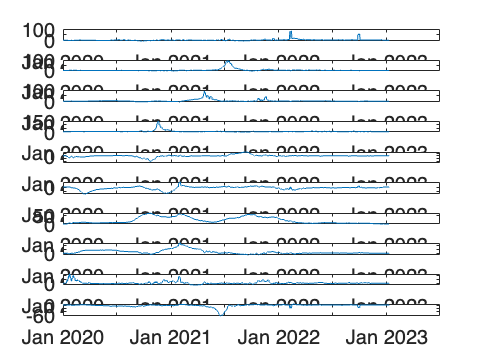




Mdl3 = rica(deathspermillion,10);
unmixed3 = transform(Mdl3,deathspermillion);

figure("Name","ica with per million data")
for i=1:10
subplot(10,1,i)
plot(dates_voc,unmixed3(:,i))%Each column of score corresponds to one independent component. 
end

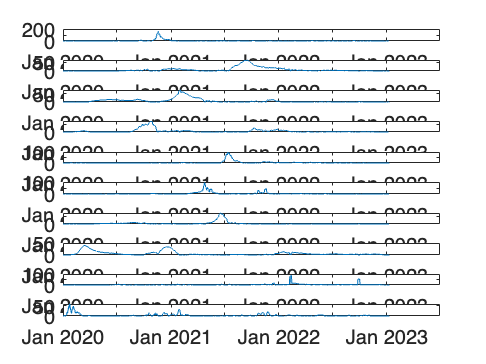



[W3,H3] = nnmf(deathspermillion,10);

figure("Name","nnmf with per million data")
for i=1:10
subplot(10,1,i)
plot(dates_voc,W3(:,i)) 
end



[idx3,C3] = kmeans(transpose(deathspermillion),10);


figure("Name","kmc with per million data")
for i=1:10
subplot(10,1,i)
plot(dates_voc,C3(i,:)) %centers of clusters
end



[id,c]=spectralcluster(coeff3,10);

[id1,c1]=spectralcluster(Mdl3.TransformWeights,10);

[id2,c2]=spectralcluster(transpose(H3),10);

%[id3,c3]=kmeans(transpose(C3),10);


c_pca="";
v1=zeros(1,200);
for i=1:10
    v2=wanted_countries(find(id==i));
    v2_pad = padarray(v2, [0, size(v1, 2) - size(v2, 2)], 'post');
    if i==1
        c_pca=v2_pad;
    else
        c_pca=cat(1,c_pca,v2_pad);
    end
end
 clear v1;
 clear v2_pad;
 clear v2;




 c_ica="";
v1=zeros(1,200);
for i=1:10
    v2=wanted_countries(find(id1==i));
    v2_pad = padarray(v2, [0, size(v1, 2) - size(v2, 2)], 'post');
    if i==1
        c_ica=v2_pad;
    else
        c_ica=cat(1,c_ica,v2_pad);
    end
end
 clear v1;
 clear v2_pad;
 clear v2;



  c_nnmf="";
v1=zeros(1,200);
for i=1:10
    v2=wanted_countries(find(id2==i));
    v2_pad = padarray(v2, [0, size(v1, 2) - size(v2, 2)], 'post');
    if i==1
        c_nnmf=v2_pad;
    else
        c_nnmf=cat(1,c_nnmf,v2_pad);
    end
end
 clear v1;
 clear v2_pad;
 clear v2;


  c_kmc="";
v1=zeros(1,200);
for i=1:10
    v2=wanted_countries(find(idx3==i));
    v2_pad = padarray(v2, [0, size(v1, 2) - size(v2, 2)], 'post');
    if i==1
        c_kmc=v2_pad;
    else
        c_kmc=cat(1,c_kmc,v2_pad);
    end
end
 clear v1;
 clear v2_pad;
 clear v2;





